# Plan Mobile Robot Paths Using RRT

This example shows how to use the rapidly exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

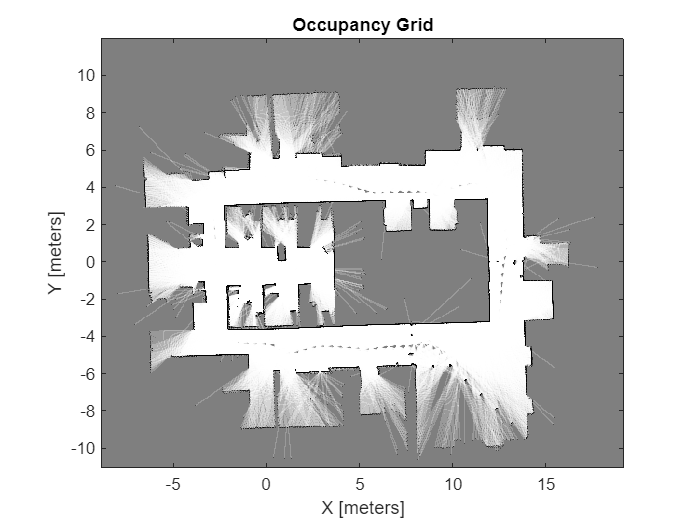

clc;
clear;
load("office_area_gridmap.mat","occGrid")
show(occGrid)


% to make the position of the robot as a obstacle for the other drones
% setOccupancy(occGrid,[0,0], 1) 
% inflate(occGrid,0.1);
nAgents = input("Enter number of agents!")

nAgents = 2


agentMat = zeros(nAgents, 3);
goalMat = zeros(nAgents, 3);

for i = 1:nAgents
    agentInput = input(['Enter agent' num2str(i) ' start X, start Y, start heading (comma-separated): '], 's');
    agentData = str2double(strtrim(strsplit(agentInput, ',')));
    agentMat(i, :) = agentData;
end

for i = 1:nAgents
    goalInput = input(['Enter agent' num2str(i) ' goal X, goal Y, goal heading (comma-separated): '], 's');
    goalData = str2double(strtrim(strsplit(goalInput, ',')));
    goalMat(i, :) = goalData;
end



% Set start and goal poses for agent A
% %  Astart = [-1,0,-pi];
% %  Agoal = [13, 3, -pi];

% Set start and goal poses for agent B
% %  Bstart = [0,0,0];
% % Bgoal = [14,-2.25,0];

% Set start and goal poses for agent C
% % Cstart = [-2.75,-1,pi/2]
% % Cgoal = [8,-4,-pi/2]

% Set start and goal poses for agent D
% % Dstart = [-5.5, 0, pi/2]
% % Dgoal = [9.25, 3, 0]

% Set start and goal poses for agent E
% Estart = [-2.75, -3, 0]
% Egoal = [13, -6, 0]



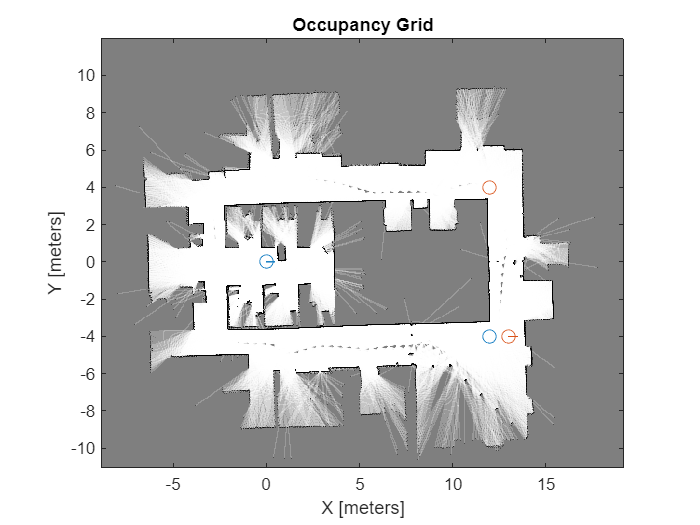


defaultColors = lines(nAgents); % Generates nAgents distinct colors
r = 0.5;
hold on

for i = 1:nAgents
    % Get color for current agent
    color = defaultColors(i, :);
    
    % Plot initial position
    plot(agentMat(i,1), agentMat(i,2), 'o', 'Color', color, 'MarkerSize', 8);
    
    % Plot final position
    plot(goalMat(i,1), goalMat(i,2), 'o', 'Color', color, 'MarkerSize', 8);
    
    % Plot direction
    plot([agentMat(i,1), agentMat(i,1) + r * cos(agentMat(i,3))], ...
         [agentMat(i,2), agentMat(i,2) + r * sin(agentMat(i,3))], '-', 'Color', color);
end

hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.  

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 1;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator for reproducible results. 

rng default
pthObj = cell(1,nAgents);
solnInfo = cell(1,nAgents);
Nodes = cell(1,nAgents);


for  i = 1:nAgents
    [pthObj{i},solnInfo{i}] = plan(planner,agentMat(i,:),goalMat(i,:));
    
end
% planning initially for agent A
% [pthObjA, solnInfoA] = plan(planner,Astart,Agoal);

for i=1:nAgents
    Nodes{i} = pthObj{i}.States;
end





% now implementing rrt between two consecutive nodes using a loop


allStates = cell(1,nAgents);
finalpath = cell(1,nAgents);
solution = cell(1,nAgents);
allNodes = zeros(1,nAgents);

for i=1:nAgents
    allNodes(i) = size(Nodes{i},1);
end
% For generating two combinations required
tempVec = 1:nAgents;
t = nchoosek(tempVec,2)

t =      1     2


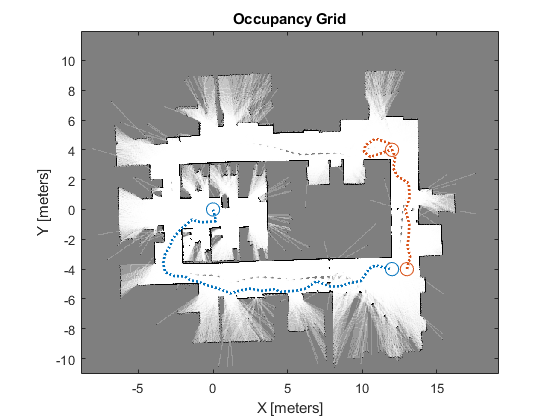



nodescount = max(allNodes); % finding the max number of nodes in the final path

for n=1:nodescount-1
    for i=1:size(t,1)
        
    index1 = t(i,1);
    index2 = t(i,2);
    statusMat = zeros(nAgents);
    


if (n>=allNodes(index1) && n<=allNodes(index2))
%     disp("Agent1 pahunch gya, Agent2 update karo")
    if(sqrt((Nodes{index2}(n,1) - Nodes{index1}(allNodes(index1),1))^2 + (Nodes{index2}(n,2) - Nodes{index1}(allNodes(index1),2))^2) < 0.5)
%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
        statusMat(index1) = 1;
        statusMat(index2) = 0;
        
    

        [finalpath{index2},solution{index2}] = interplanner(allNodes(index1),Nodes{index1},Nodes{index2},statusMat(index1),statusMat(index2));

        allStates{index2} = [allStates{index2};finalpath{index2}.States(:,:)];

    end
   

    
elseif(n<=allNodes(index1) && n>=allNodes(index2))
%     disp("Agent2 pahunch gya, Agent1 update karo")

        if(sqrt((Nodes{index2}(allNodes(index2),1) - Nodes{index1}(n,1))^2 + (Nodes{index2}(allNodes(index2),2) - Nodes{index1}(n, 2))^2) < 0.5)
%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
            statusMat(index1) = 0;
            statusMat(index2) = 1;
        
  
            [finalpath{index1},solution{index1}] = interplanner(allNodes(index2),Nodes{index1},Nodes{index2},statusMat(index1),statusMat(index2));

            allStates{index1} = [allStates{index1};finalpath{index1}.States(:,:)];

        end
    
    
else
    %% Insert some condition to avoid error!
    if(n>allNodes(index1) || n>allNodes(index2))
    
    else
        
    
        if(sqrt((Nodes{index1}(n,1) - Nodes{index2}(n,1))^2 + (Nodes{index1}(n,2) - Nodes{index2}(n,2))^2) < 1)
%             disp("Agent1 and Agent2 ka distance is less than 0.5")
            statusMat(index1) = 0;
            statusMat(index2) = 1;
            
            [finalpath{index2},solution{index2}] = interplanner(n,Nodes{index1},Nodes{index2},statusMat(index2),statusMat(index1));
            
   
            allStates{index2} = [allStates{index2};finalpath{index2}.States(:,:)];

    
    

        else

          
        end   
    end
        

end
    


for k=1:nAgents
    if(n < allNodes(k))
    allStates{k} = [allStates{k};pthObj{k}.States(n,:)];
    end
end


% Show the occupancy grid
% Generate a colormap with nAgents distinct colors
colors = lines(nAgents);

show(occGrid);
hold on;

for m = 1:nAgents
    % Get color for current agent
    color = colors(m, :);
    
    % Plot initial position
    plot(agentMat(m,1), agentMat(m,2), 'o', 'Color', color, 'MarkerSize', 10);
    
    % Plot final position
    plot(goalMat(m,1), goalMat(m,2), 'o', 'Color', color, 'MarkerSize', 10);
    
    % Plot all states
    plot(allStates{m}(:,1), allStates{m}(:,2), '-', 'Color', color, 'LineWidth', 2, 'LineStyle', ':');
    
    % Plot final path if it exists
    if n < allNodes(m)
        if ~isempty(evalin('base', sprintf('who("finalpath{%d}")', m)))
            plot(finalpath{m}(:,1), finalpath{m}(:,2), '-', 'Color', color, 'LineWidth', 2, 'LineStyle', ':');
        end
    end
end

hold off;







hold off 


% Pause for a short duration to allow figure to update
pause(0.1); % Adjust the duration as needed
    end
end

% plotting the path simultaneously for both the agents
% creating a function in which I will send the points for the agents. 


## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

% show(occGrid)
% hold on
% 
% % Plot entire search tree.
% plot(solnInfoA.TreeData(:,1),solnInfoA.TreeData(:,2),'.-');
% 
% % Interpolate and plot path.
% interpolate(pthObjA,300)
% plot(pthObjA.States(:,1),pthObjA.States(:,2),'r-','LineWidth',2)
% 
% % Show start and goal in grid map.
% plot(Astart(1),Astart(2),'ro')
% plot(Agoal(1),Agoal(2),'mo')
% 
% 
% 
% % Plot entire search tree.
% plot(solnInfoB.TreeData(:,1),solnInfoB.TreeData(:,2),'.-');
% 
% % Interpolate and plot path.
% interpolate(pthObjB,300)
% plot(pthObjB.States(:,1),pthObjB.States(:,2),'b-','LineWidth',2)
% 
% % Show start and goal in grid map.
% plot(Bstart(1),Bstart(2),'ro')
% plot(Bgoal(1),Bgoal(2),'mo')
% 
% 
% hold off

## Customize Dubins Vehicle Constraints

To specify custom vehicle constraints, customize the state space object. This example uses `ExampleHelperStateSpaceOneSidedDubins`, which is based on the `stateSpaceDubins` class. This helper class limits the turning direction to either right or left based on a Boolean property, `GoLeft`. This property essentially disables path types of the `dubinsConnection` object.

Create the state space object using the example helper. Specify the same state bounds and give the new Boolean parameter as `true` (left turns only).

% % Only making left turns
% goLeft = true;
% 
% % Create the state space
% ssCustom = ExampleHelperStateSpaceOneSidedDubins(bounds,goLeft);
% ssCustom.MinTurningRadius = 0.4;

## Plan Path

Create a new planner object with the custom Dubins constraints and a validator based on those constraints. Specify the same `GoalReached` function.

% stateValidator2 = validatorOccupancyMap(ssCustom); 
% stateValidator2.Map = occGrid;
% stateValidator2.ValidationDistance = 0.05;
% 
% planner = plannerRRT(ssCustom,stateValidator2);
% planner.MaxConnectionDistance = 2.0;
% planner.MaxIterations = 30000;
% planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator again.

% rng default
% [pthObj2,solnInfo] = plan(planner,start,goal);

## Plot Path

Draw the new path on the map. The path should only execute left turns to reach the goal.

% figure
% show(occGrid)
% 
% hold on
% 
% % Show the search tree.
% plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');
% 
% % Interpolate and plot path.
% pthObj2.interpolate(300)
% plot(pthObj2.States(:,1), pthObj2.States(:,2), 'r-', 'LineWidth', 2)
% 
% % Show start and goal in grid map.
% plot(start(1), start(2), 'ro')
% plot(goal(1), goal(2), 'mo')
% hold off




*Copyright 2019 The MathWorks, Inc.*